# ***Forward_Modeling_grid.mlx***

Το script αυτό πραγματοποιεί τη διαδικασία του Forward Modeling ενός ρήγματος Uniform Slip σε επιλεγμένα σημεία-σταθμούς στην επιφάνεια του εδάφους, διατεταγμένα σε πλέγμα γύρω από το ρήγμα.

Αρχικά θέτουμε ως θέση που τρέχει η Matlab το εσωτερικό του φακέλου 'Project'. Όπου υπάρχει σε σχόλιο το "-->", η μεταβλητή πρέπει να εισαχθεί από το χρήστη ανάλογα με τα δεδομένα του προβλήματος. 

# Forward Modeling (Grid Area)

% Copyright (c) 2018, Livadas – Stathakopoulos Ioannis (yiannislibad@hotmail.gr)
% Covered by MIT Licence
% Πραγματοποιείται εντός αναφορά σχετικά με χρήση scripts ή λογισμικού τρίτων.

% Επιτρέπουμε στη Matlab να έχει πρόσβαση στα περιεχόμενα του φακέλου Project
folder = fileparts(which('Forward_Modeling_grid.mlx'));
addpath(genpath(folder));
clearvars

## Εισαγωγή Δεδομένων

Αρχικά δίνουμε τις τιμές των χαρακτηριστικών του ρήγματος.

Depth = 0.5;           % --> Top Depth, σε km
Strike = 315;          % --> Strike, σε μοίρες
Dip = 45;              % --> Dip, σε μοίρες
Leng = 12;             % --> Lenth, σε km
Wid = 7;               % --> Width, σε km
Rake = 270;            % --> Rake, σε μοίρες
Slip = 0.00075;        % --> Slip, σε km

% Αφού το Slip δίνεται σε km και τα υπόλοιπα μήκη σε km, το Factor = 1/1 = 1

Depth_c = Depth + sin(Dip*pi/180)*Wid/2; ...
    % Η okada85 ζητά το Depth του fault centroid

Slip_Scale = 0.5 * 10^6; % Η κλίμακα των slip για την καλύτερη αναπαράσταση τους
    % Εδώ π.χ. 1 km στο γράφημα θα αντιστοιχεί σε 10^3/Slip_Scale (m) = 5mm
    
Slip_Scale_z = 4 * Slip_Scale;    % -->  Η κλίμακα των uZ slip

Δίνουμε και τις συντεταγμένες του κέντρου του ρήγματος σε μορφή [degrees minutes seconds]. Υπολογίζονται τα northing και easting του κέντρου σε km, με χρήση του script 'll2utm.m' του François Beauducel. Κάθε φορά που ακολουθείται η ίδια ή η αντίστροφη μετατροπή (latitude-longitude <-> UTM), χρησιμοποιούνται τα script 'll2utm.m' και 'utm2ll.n' του François Beauducel.

latitude_c = [39 34 22];      % --> Latitude, N του fault centroid
longitude_c = [22 34 40];     % --> Longitude, E του fault centroid

lat_c = dms2degrees(latitude_c);
long_c = dms2degrees(longitude_c);

[E_c,N_c] = ll2utm(lat_c,long_c);
N_c = N_c/1000; E_c = E_c/1000;  % Συντεταγμένες UTM του fault centroid σε km

## Ίχνος Ρήγματος (Fault Trace)

Υπολογίζεται και το ίχνος του ρήγματος (προέκταση του στην επιφάνεια του εδάφους).

trace_A_N = sin(Strike*pi/180)*(Wid/2 + Depth/tan(Dip*pi/180))...
    - cos(Strike*pi/180)*Leng/2;
trace_B_N = sin(Strike*pi/180)*(Wid/2 + Depth/tan(Dip*pi/180))...
    + cos(Strike*pi/180)*Leng/2;

trace_A_E = -cos(Strike*pi/180)*(Wid/2 + Depth/tan(Dip*pi/180))...
    - sin(Strike*pi/180)*Leng/2;
trace_B_E = -cos(Strike*pi/180)*(Wid/2 + Depth/tan(Dip*pi/180))...
    + sin(Strike*pi/180)*Leng/2;

N_trace = linspace(trace_A_N,trace_B_N,100);  % Το Northing του ίχνους
E_trace = linspace(trace_A_E,trace_B_E,100);  % Το Easting του ίχνους
Z_trace = zeros(100);

Βρίσκονται οι συντεταγμένες των δύο σημείων που ορίζουν το ευθύγραμμο τμήμα του ίχνους.

**!!! Προσοχή! Εάν το ρήγμα βρίσκεται στο νότιο ημισφαίριο, η τιμή του zone (utm) θέλει αρνητική τιμή (-) κατά τη χρήση στο script 'utm2ll' !!!**

zone = utmzone(lat_c,long_c);
zone(end) = [];
zone_num = str2double(zone);

[lat_A,long_A] = utm2ll((E_c+trace_A_E)*1000,(N_c+trace_A_N)*1000,...
    zone_num);

[lat_B,long_B] = utm2ll((E_c+trace_B_E)*1000,(N_c+trace_B_N)*1000,...
    zone_num);

## Συνθετικά Δεδομένα

Τα συνθετικά δεδομένα που θα παράγουμε εδώ θα αποτελούν μετρήσεις σε ένα πλέγμα (ορθογώνιο) σημείων του χώρου γύρω από το κέντρο του ρήγματος. Δίνουμε τις τιμές των άκρων του ορθογωνίου, σε km στις διευθύνσεις East και North, καθώς και τον αριθμό των σημείων ανά πλευρά.

Emin = -15; Emax = 15;  % --> Έκταση Easting του πλέγματος
Nmin = -15; Nmax = 15;  % --> Έκταση Northing του πλέγματος
points_E = 5; points_N = 5; % --> Αριθμός σημείων ανά πλευρά
points_grid = points_E*points_N;
    % Προσοχή, το sdm2011.exe έχει περιορισμό στον αριθμο
        % σημείων που θα εισάγουμε!

% Δημιουργία πλέγματος σημείων
[Egrid,Ngrid] = meshgrid(linspace(Emin,Emax,points_E),...
    linspace(Nmin,Nmax,points_N));
Zgrid = zeros(points_N,points_E);

% Διάταξη Easting και Northing των σημείων σε μία στήλη
Egrid_trans = Egrid(:);
Ngrid_trans = Ngrid(:);
Zgrid_trans = Zgrid(:);

% Όνομα σταθμών για απεικόνιση
grid_names = num2str((1:points_E*points_N)');

% Συντεταγμένες σταθμών σε latitude, longitude
[lat_grid_trans,long_grid_trans] = utm2ll((E_c+Egrid_trans)*...
    1000,(N_c+Ngrid_trans)*1000,zone_num);
coordinates_grid_trans = [lat_grid_trans long_grid_trans];

table_grid = [Egrid_trans Ngrid_trans Egrid_trans+E_c ...
    Ngrid_trans+N_c long_grid_trans lat_grid_trans]; ...
    % Πίνακας για χρήση στο excel

Υπολογίζονται τα uE, uN και uZ του πλέγματος σημείων, που εκφράζουν τις μετακινήσεις τους, με τη διαδικασία του Forward Modeling.

[uEgrid,uNgrid,uZgrid] = okada85_ed1(Egrid,Ngrid,...
    Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);

% Διάταξη των ολισθήσεων σε μία στήλη
uEgrid_trans = uEgrid(:);
uNgrid_trans = uNgrid(:);
uZgrid_trans = uZgrid(:);

Δίνεται το σφάλμα των μετρήσεων. Επιλέγουμε το ίδιο με το μικρό σφάλμα της αρχικής περίπτωσης (3mm οριζόντιες μετακινήσεις, 5mm κατακόρυφες μετακινήσεις).

sigma_uE = 3*10^-6; % --> Το σφάλμα μέτρησης στη διεύθυνση E σε km
sigma_uN = 3*10^-6; % --> Το σφάλμα μέτρησης στη διεύθυνση N σε km
sigma_uZ = 5*10^-6; % --> Το σφάλμα μέτρησης στη διεύθυνση Z σε km

Σχεδιάζονται ρήγμα και ολισθήσεις των σημείων στο επίπεδο East, North.

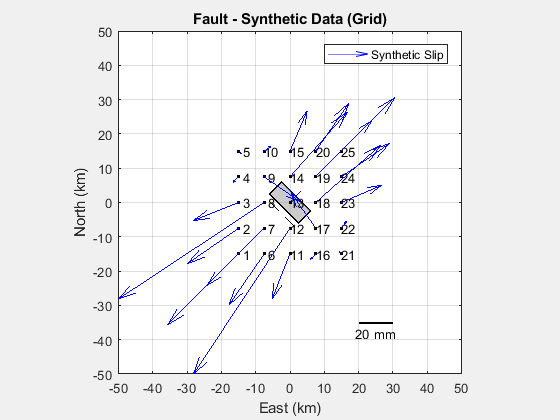

figure()

% Απεικόνιση του ρήγματος
okada85_ed1(Egrid,Ngrid,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
hold on

% Απεικόνιση των σημείων - σταθμών
plot3(Egrid,Ngrid,Zgrid,'.k')
text(Egrid_trans,Ngrid_trans,Zgrid_trans,grid_names);

% Απεικόνιση των συνθετικών δεδομένων
p1 = quiver3(Egrid,Ngrid,Zgrid,uEgrid*Slip_Scale,...
    uNgrid*Slip_Scale,uZgrid*Slip_Scale,'b',...
    'AutoScale','off','MaxHeadSize',0.1);

% Σχεδίαση του ίχνους
plot3(E_trace,N_trace,Z_trace,'k--')

% Υπόμνημα
leg = legend(p1,'Synthetic Slip');
leg.AutoUpdate = 'off';
leg.Location = 'northeast';

% Τα ticks των αξόνων
xticks(-500:10:500)
yticks(-500:10:500)
zticks(-500:10:500)

% Δημιουργία μπάρας κλίμακας για το μέγεθος των ολισθήσεων
obj = scalebar_ed1;
obj.XLen = 10; obj.YLen = 0;
obj.XUnit = [num2str(1/Slip_Scale*10^6*obj.XLen) ' mm'];
obj.hTextX_Pos = [-1,-3];
obj.Position = [20,-35];

% Labels, εύρος αξόνων, γωνία προβολής και τίτλος
xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
axis([-50 50 -50 50 -20 20])  % --> Μεταβάλλω ανάλογα
view([0 90]);                   % Για προβολή από πάνω
title('Fault - Synthetic Data (Grid)')

Και για τις κατακόρυφες ολισθήσεις:

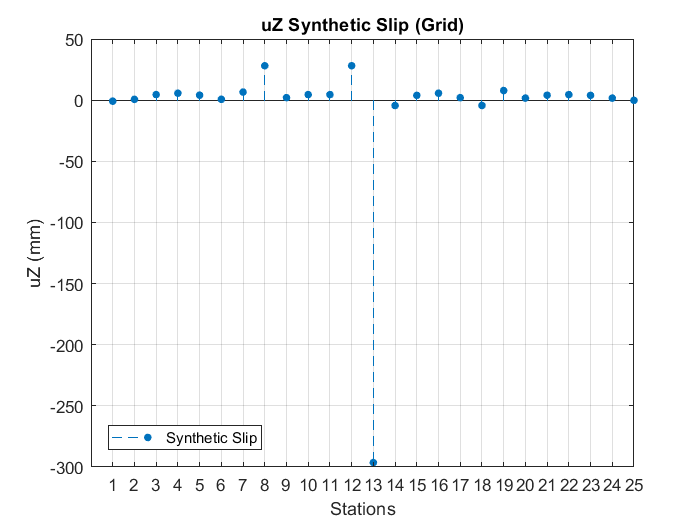

figure()

% Απεικόνιση συνθετικών κατακόρυφων μετρήσεων- "προβλέψεων" 
    % (μικρό-μεγάλο σφάλμα) κατακόρυφων ολισθήσεων (μορφή stems)
p1 = stem(1:points_grid,uZgrid_trans*10^6,...
    'filled','MarkerSize',4,'LineStyle','--');

% Υπόμνημα
leg = legend(p1,'Synthetic Slip');
leg.AutoUpdate = 'off';
leg.Location = 'southwest';

% Ticks, Labels και τίτλος
grid on
xticks(1:points_grid);
xlabel('Stations'); ylabel('uZ (mm)')
title('uZ Synthetic Slip (Grid)');

# Προσθήκη θορύβου

## Θόρυβος στα συνθετικά δεδομένα (σh - 3mm, σv - 5mm)

Θα προσθέσουμε θόρυβο στα συνθετικά δεδομένα (grid), σύμφωνα με το σφάλμα μετρήσεων που διαθέτουμε (3mm στις οριζόντιες μετακινήσεις και 5mm στις κατακόρυφες). Δημιουργήσουμε 10 νέα σύνολα μετατοπίσεων.

n_models = 10;  % --> Αριθμός μοντέλων με θόρυβο

sigma_uE_t = repmat(sigma_uE,1,n_models);
sigma_uN_t = repmat(sigma_uN,1,n_models);
sigma_uZ_t = repmat(sigma_uZ,1,n_models);

**!!! Εάν τρέξουμε το βήμα αυτό δημιουργούνται νέα μοντέλα, καθώς δημιουργείται τυχαίος θόρυβος βάσει του σφάλματος !!!**

uE_noise = sigma_uE_t .* randn(points_grid,n_models);
uN_noise = sigma_uN_t .* randn(points_grid,n_models);
uZ_noise = sigma_uZ_t .* randn(points_grid,n_models);

uE_New = uE_noise + repmat(uEgrid_trans,1,n_models);
uN_New = uN_noise + repmat(uNgrid_trans,1,n_models);
uZ_New = uZ_noise + repmat(uZgrid_trans,1,n_models);

% Υπολογισμός SNR
SNR_uE = zeros(1,n_models);
SNR_uN = zeros(1,n_models);
SNR_uZ = zeros(1,n_models);

for count = 1:n_models
    
    start = (count-1)*3 + 1;
    
    % Πίνακας slips για χρήση στο Excel (cm)
    table_slips_New(:,start:start+2) = [uE_New(:,count) ...
        uN_New(:,count) uZ_New(:,count)]*10^5;

    SNR_uE(count) = snr(uEgrid_trans,uE_noise(:,count));
    SNR_uN(count) = snr(uNgrid_trans,uN_noise(:,count));
    SNR_uZ(count) = snr(uZgrid_trans,uZ_noise(:,count));
        
end

% Αποθήκευση του Workspace
save Workspace_ForwardModeling_grid.mat